# Color Histogram

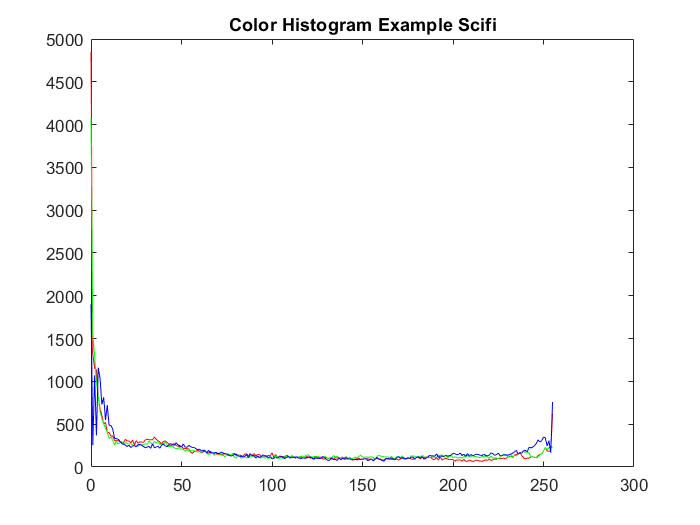

myFolder = 'C:\Users\kfoster\Desktop\QEA\QEA_Module_2\Posters\Scifi\Train';
if ~isdir(myFolder)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', myFolder);
  uiwait(warndlg(errorMessage));
  return;
end
filePattern = fullfile(myFolder, '*.jpg');
jpegFilesSci = dir(filePattern);
totalRed = zeros(268,182);
totalGreen = zeros(268,182);
totalBlue = zeros(268,182);
for k = 1:length(jpegFilesSci)
  baseFileName = jpegFilesSci(k).name;
  fullFileName = fullfile(myFolder, baseFileName);
  %fprintf(1, 'Now analyzing %s\n', fullFileName);
  image = imread(fullFileName);
  % Split into RGB channesl
  Red = image(:,:,1);
  Green = image(:,:,2);
  Blue = image(:,:,3);
  %Get histValues for each channel
  [yRed, x] = imhist(Red);
  [yGreen, x] = imhist(Green);
  [yBlue, x] = imhist(Blue);
  %Plot them together in one plot
  plot(x, yRed, 'Red', x, yGreen, 'Green', x, yBlue, 'Blue');
  title("Color Histogram Example Scifi");
  totalRed = totalRed + double(Red);
  totalGreen = totalGreen + double(Green);
  totalBlue = totalBlue + double(Blue);
end

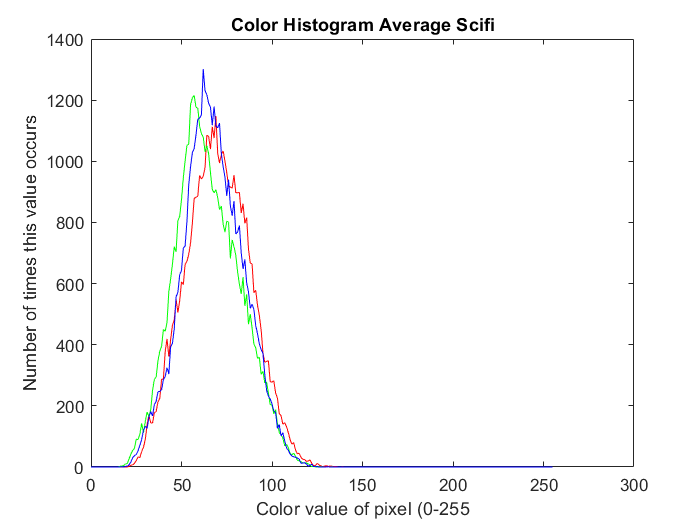


avgRedSci = totalRed./length(jpegFilesSci);
avgGreenSci = totalGreen./length(jpegFilesSci);
avgBlueSci = totalBlue./length(jpegFilesSci);
[yavgRed, x] = imhist(uint8(avgRedSci));
[yavgGreen, x] = imhist(uint8(avgGreenSci));
[yavgBlue, x] = imhist(uint8(avgBlueSci));

plot(x, yavgRed, 'Red', x, yavgGreen, 'Green', x, yavgBlue, 'Blue');

title("Color Histogram Average Scifi");
xlabel("Color value of pixel (0-255");
ylabel("Number of times this value occurs")

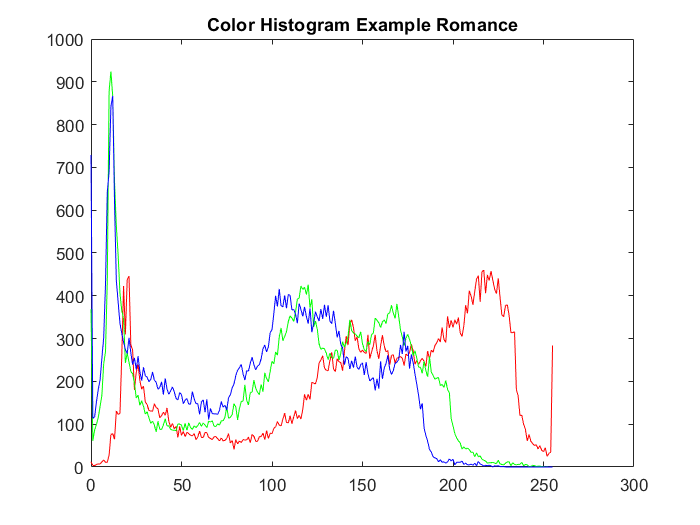

clear k
myFolder = 'C:\Users\kfoster\Desktop\QEA\QEA_Module_2\Posters\Romance\Train';
if ~isdir(myFolder)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', myFolder);
  uiwait(warndlg(errorMessage));
  return;
end
filePattern = fullfile(myFolder, '*.jpg');
jpegFilesRom = dir(filePattern);
totalRed = zeros(268,182);
totalGreen = zeros(268,182);
totalBlue = zeros(268,182);
for k = 1:length(jpegFilesRom)
  baseFileName = jpegFilesRom(k).name;
  fullFileName = fullfile(myFolder, baseFileName);
  %fprintf(1, 'Now analyzing %s\n', fullFileName);
  image = imread(fullFileName);
  % Split into RGB channesl
  Red = image(:,:,1);
  Green = image(:,:,2);
  Blue = image(:,:,3);
  %Get histValues for each channel
  [yRed, x] = imhist(Red);
  [yGreen, x] = imhist(Green);
  [yBlue, x] = imhist(Blue);
  %Plot them together in one plot
  plot(x, yRed, 'Red', x, yGreen, 'Green', x, yBlue, 'Blue');
  title("Color Histogram Example Romance");
  totalRed = totalRed + double(Red);
  totalGreen = totalGreen + double(Green);
  totalBlue = totalBlue + double(Blue);
end

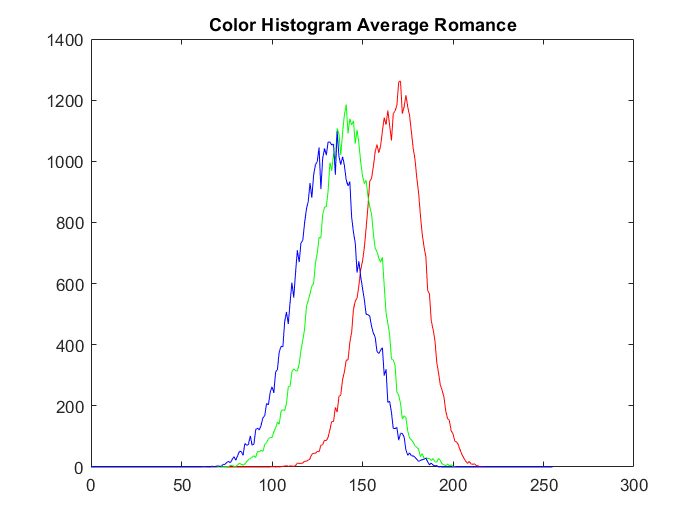


avgRedRom = totalRed./length(jpegFilesRom);
avgGreenRom = totalGreen./length(jpegFilesRom);
avgBlueRom = totalBlue./length(jpegFilesRom);
[yavgRed, x] = imhist(uint8(avgRedRom));
[yavgGreen, x] = imhist(uint8(avgGreenRom));
[yavgBlue, x] = imhist(uint8(avgBlueRom));

plot(x, yavgRed, 'Red', x, yavgGreen, 'Green', x, yavgBlue, 'Blue');
title("Color Histogram Average Romance");

xlabel("Color value of pixel (0-255");
ylabel("Number of times this value occurs")
clear k

## Sort Images 

Takes new image, determiens wheter that image's histogram is closer to the scifi or romance histogram


num_true = 0;
num_false = 0;
%false_list = [];

myFolder = 'C:\Users\kfoster\Desktop\QEA\QEA_Module_2\Posters\Scifi\Test';
if ~isdir(myFolder)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', myFolder);
  uiwait(warndlg(errorMessage));
  return;
end
filePattern = fullfile(myFolder, '*.jpg');
jpegFilesRom = dir(filePattern);
for n = 1:length(jpegFilesRom)
  baseFileName = jpegFilesRom(n).name;
  fullFileName = fullfile(myFolder, baseFileName);
  image = imread(fullFileName);
  % Split into RGB channesl
  Red = image(:,:,1);
  Green = image(:,:,2);
  Blue = image(:,:,3);
  
  
  SciDiff = sum(abs(uint8(avgRedSci)-Red))+sum(abs(uint8(avgGreenSci)-Green))+sum(abs(uint8(avgBlueSci)-Blue));
  RomDiff = sum(abs(uint8(avgRedRom)-Red))+sum(abs(uint8(avgGreenRom)-Green))+sum(abs(uint8(avgBlueRom)-Blue));
  
  if SciDiff>RomDiff
      disp("Rom")
  else
      disp("Sci")
  end
end

Sci
Sci
Sci
Sci
Sci
Sci
Sci
Sci
Sci
Sci
Sci
Sci
Sci
Sci
Sci
Sci
Sci
